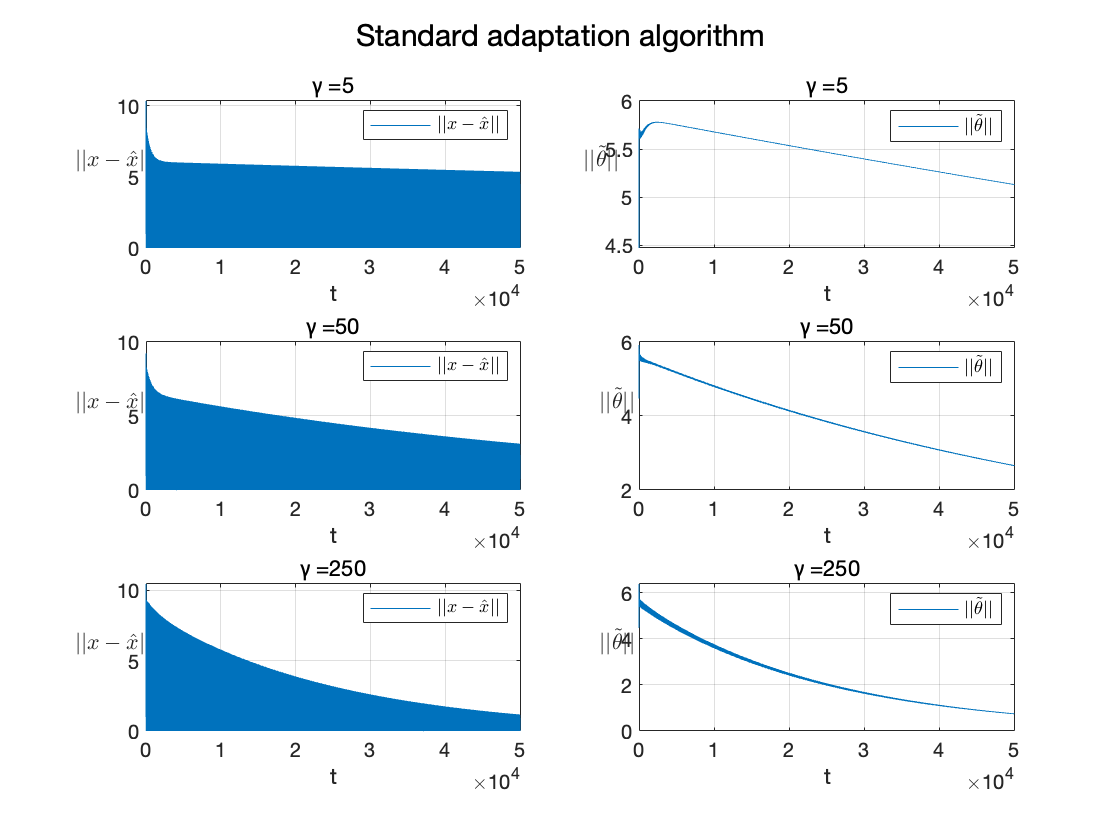

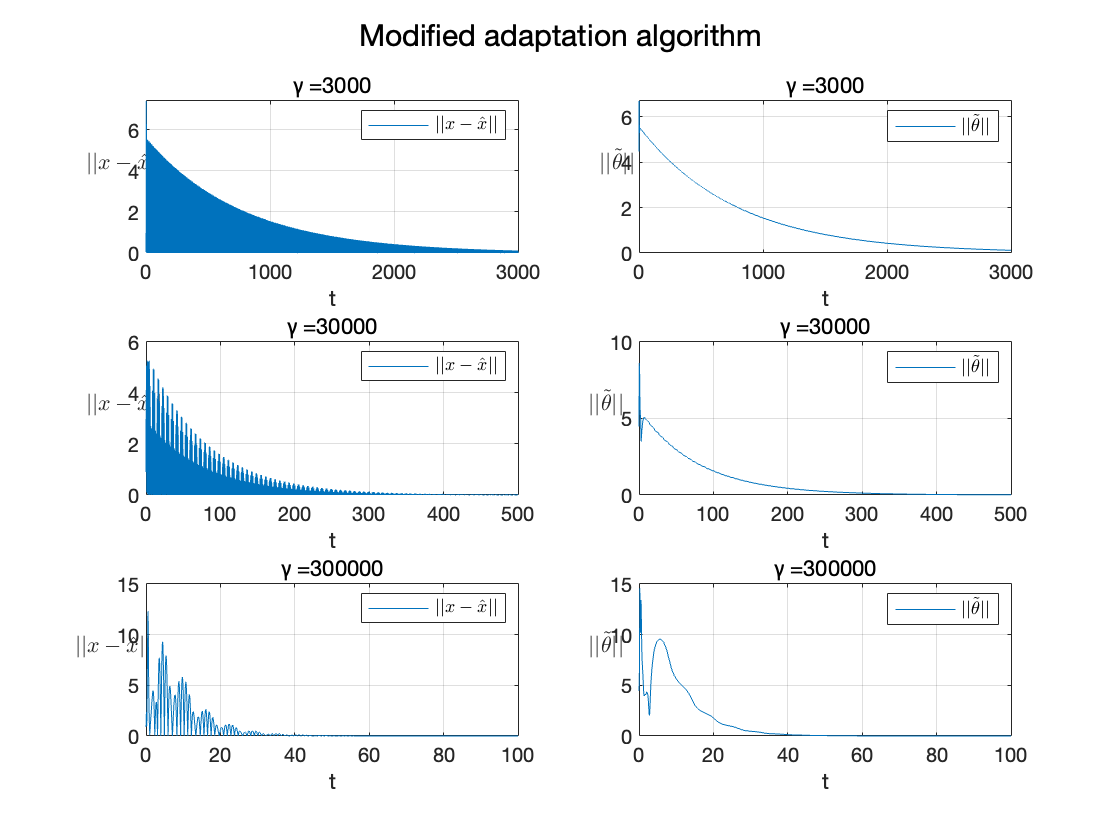

clear

a1 = 7;
a0 = 10;
b1 = 2;
b0 = 6;
k1 = 5;
k0 = 6;

A = [-a1 1; -a0 0];
b = [b1; b0];
C = [1 0];

A0 = [0 1; -k0 -k1];
A0_ = [-k1 1; -k0 0];
e1 = [1; 0];
e2 = [0; 1];

theta1 = k0-a0;
theta2 = k1-a1;
theta3 = b0;
theta4 = b1;

theta = [theta1; theta2; theta3; theta4];

% algorithmSelect = 1; % 1: standard adaptation algorithm
%                      % 2: modified adaptation algorithm
% switch algorithmSelect
%     case 1
%         gamma = 50;
%         T = 150000;
%     case 2
%         gamma = 3000;
%         T = 1500;
% end

for algorithmSelect = 1:1:2
figure(algorithmSelect)
    for testNum = 1:1:3
        [gamma T Title] = parameterSelect(algorithmSelect,testNum);
        out = sim("TP.slx");
        t = out.tout;
        e = out.simout.Data;
        e_norm = sqrt(e(:,1).^2 + e(:,2).^2);
        theta_tilde = out.simout1.Data;
        theta_tilde_norm = sqrt(theta_tilde(:,1).^2 + theta_tilde(:,2).^2);
    
        subplot(3,2,2*testNum-1)
        plot(t,e_norm);
        grid on;
        xlabel('t')
        ylabel('$||x-\hat{x}||$', 'Interpreter', 'latex', 'Rotation', 0)
        legend('$||x-\hat{x}||$', 'Interpreter', 'latex') 
        title(strcat('γ = ', num2str(gamma)))
        
        subplot(3,2,2*testNum)
        plot(t,theta_tilde_norm);
        grid on;
        xlabel('t')
        ylabel('$||\tilde{\theta}||$', 'Interpreter', 'latex', 'Rotation',0)
        legend('$||\tilde{\theta}||$', 'Interpreter', 'latex')
        title(strcat('γ = ', num2str(gamma)))
        
        sgtitle(Title);
    end
end

function [gamma T Title] = parameterSelect(algorithmSelect, testNum)
    switch algorithmSelect
        case 1 % 1: standard adaptation algorithm
             switch testNum
                 case 1
                    gamma = 5;
                    T = 50000;
                 case 2
                    gamma = 50;
                    T = 50000;
                 case 3
                    gamma = 250;
                    T = 50000;
             end
             Title = 'Standard adaptation algorithm';
        case 2 % 2: modified adaptation algorithm
             switch testNum
                 case 1
                    gamma = 3000;
                    T = 3000;
                 case 2
                    gamma = 30000;
                    T = 500;
                 case 3
                    gamma = 300000;
                    T = 100;
             end
             Title = 'Modified adaptation algorithm';
    end
end